## MATLABチュートリアル

MATLAB （日本語では「マトラボ」，あるいは「マトラブ」と発声されることが多い）は反復的な分析と設計プロセスに適したデスクトップ環境と，行列と配列を直接表現できるプログラミング言語が 1 つに組み合わさった技術計算言語の一種です．

MATLABではツールボックスと呼ばれる様々なライブラリを駆使することで，複雑な数値計算を容易に実行することができます．

ここではMATLABの基本的な文法・ツールについて解説します．

### MATLAB Live Editor について

MATLAB Live Editor とはライブエディターと呼ばれる形式で作成したプログラムの実行と実行結果を記録しながらデータ分析を進めるツールです．この本文のようにMarkdown形式のセルとMATLABのコードを同居させることができるので，勉強用に技術ノートなり解説なりを作ることが可能です．

また，C言語の授業で扱ったBCPADのように「実行」を押すだけでプログラムを実行できます. 皆さんが卒業研究でやるようなシミュレーションには不向きですが, プログラミングに慣れるためにはちょうどいいツールです.

MATLAB Live Editor が嫌になったらその辺の院生に声をかけてください．より良いエディタを紹介します．

### MATLAB Live Editor の基本的な使い方

ここでは画面出力「disp」を用いた文字列の表示を例に挙げ，MATLAB Live Editor の基本的な使い方を説明します．

#### 1．MATLAB Live Editor の起動

    Windows バーの左下の検索欄で「matlab」と入力して，候補で現れるMATLABを起動する．

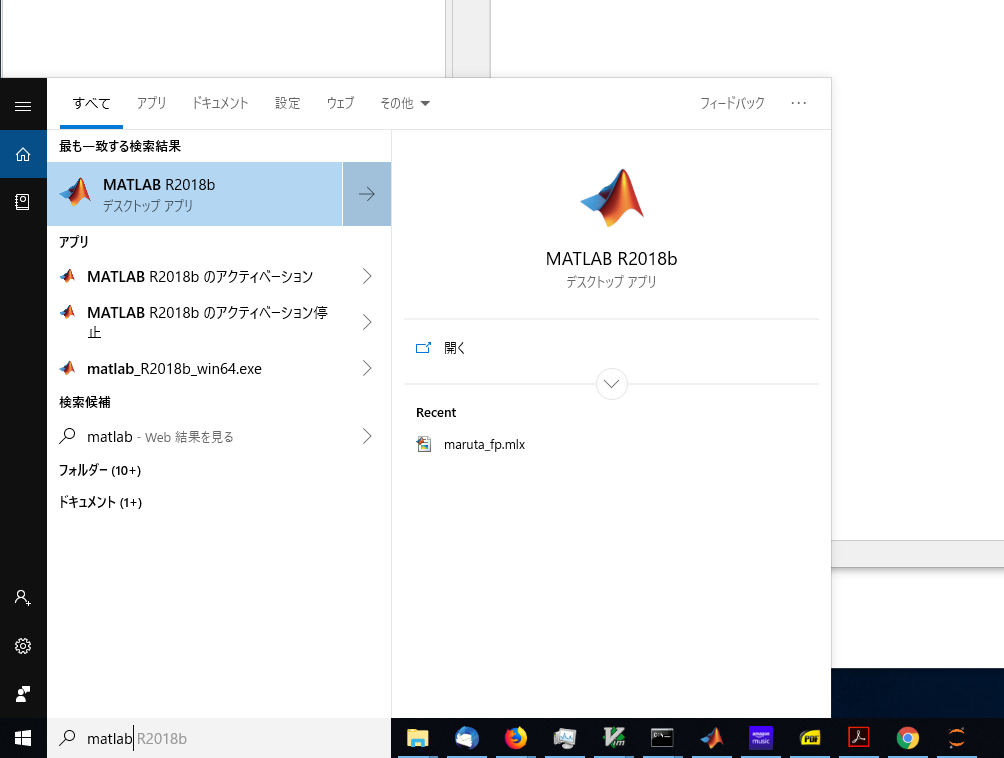

    スプラッシュ画面が表示されたあと，しばらくするとこのような画面が立ち上がります．これで起動完了です．

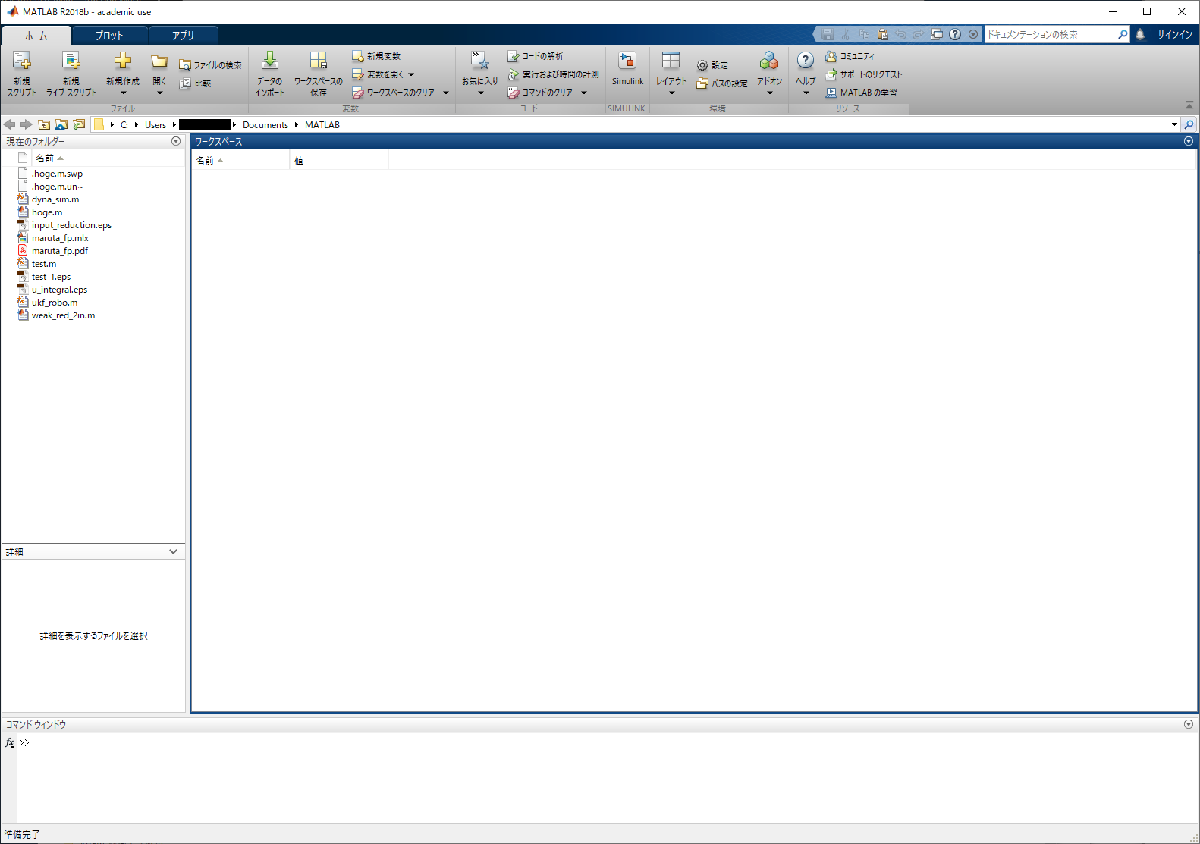

### 2． 新しいLive Script ファイルの作成

    まず以下の流れに沿って，新しいファイルを作りたいディレクトリに移動します. 

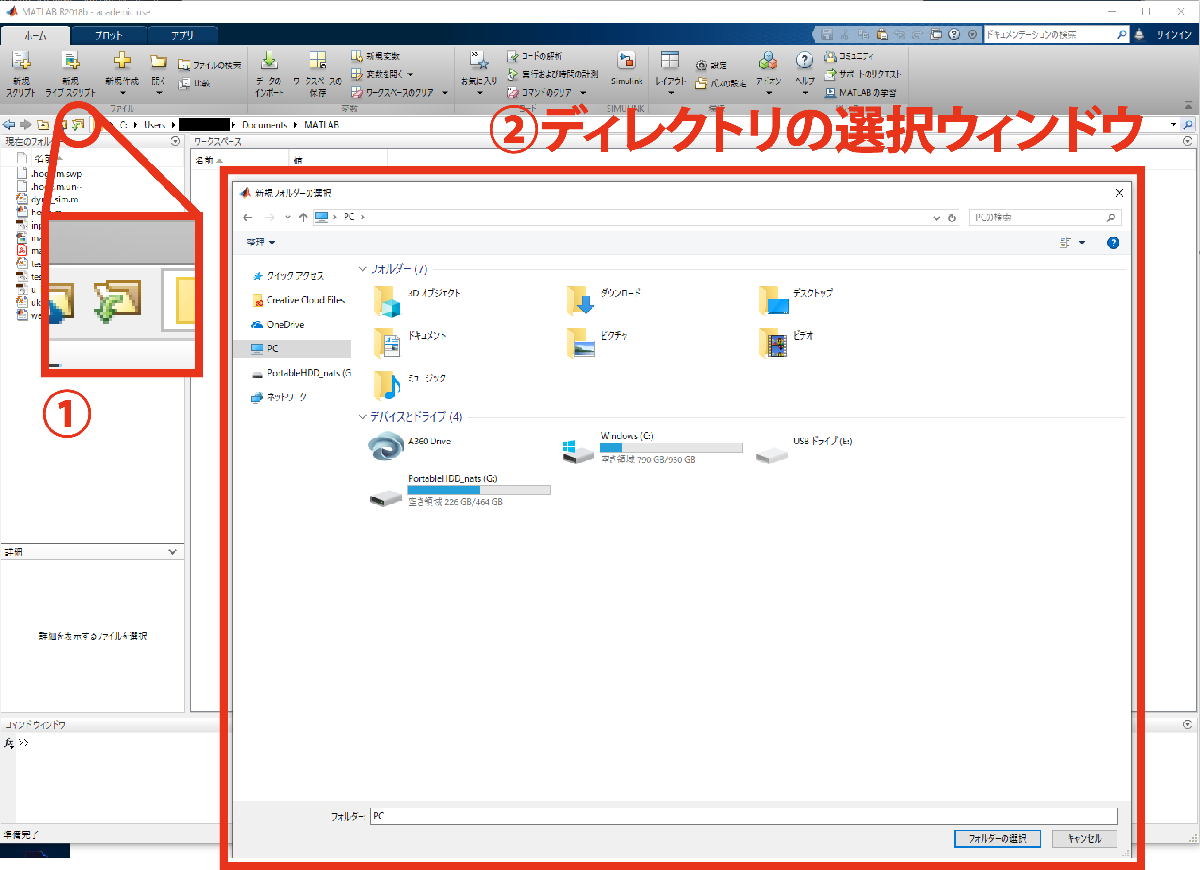

    その後メニューバーの「ホーム」をクリックし，「新規ライブスクリプト」をを選択します．

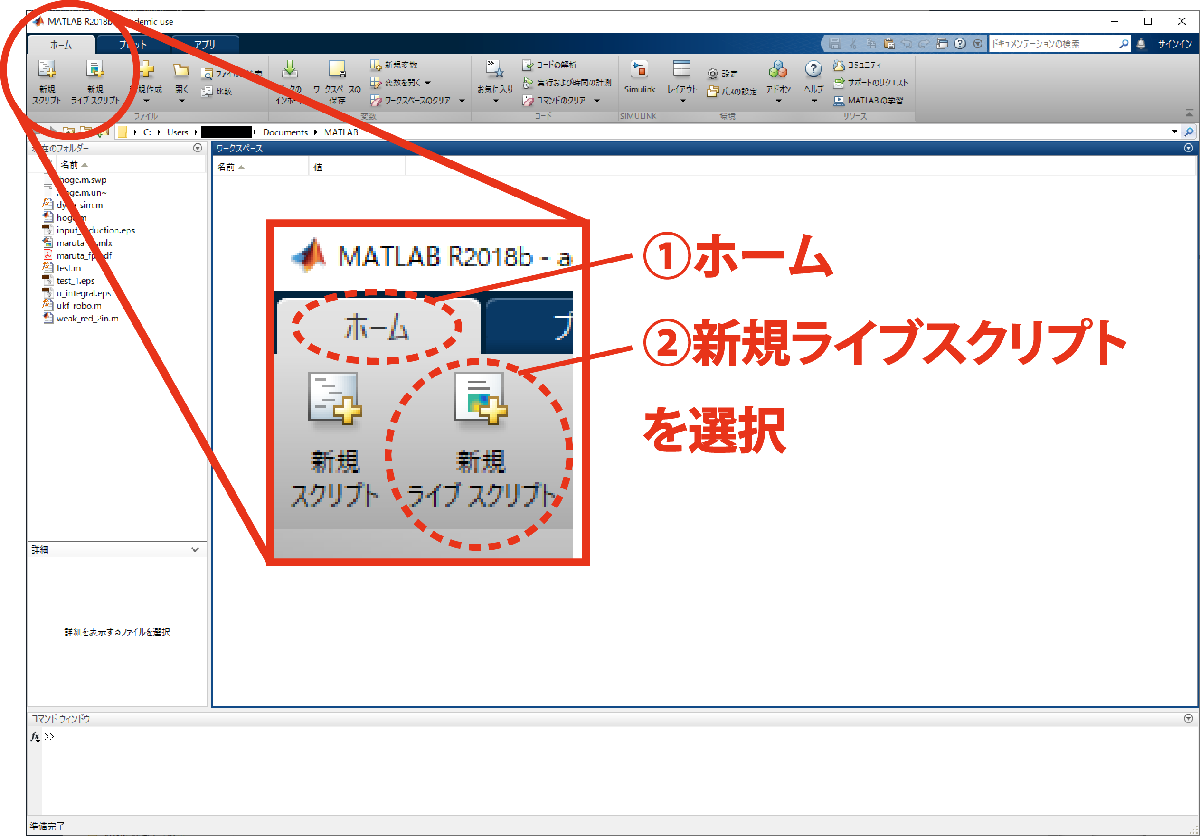

### 3.  準備完了

    MATLABを起動し，ライブスクリプトファイルを作ることができました．これで準備完了です．

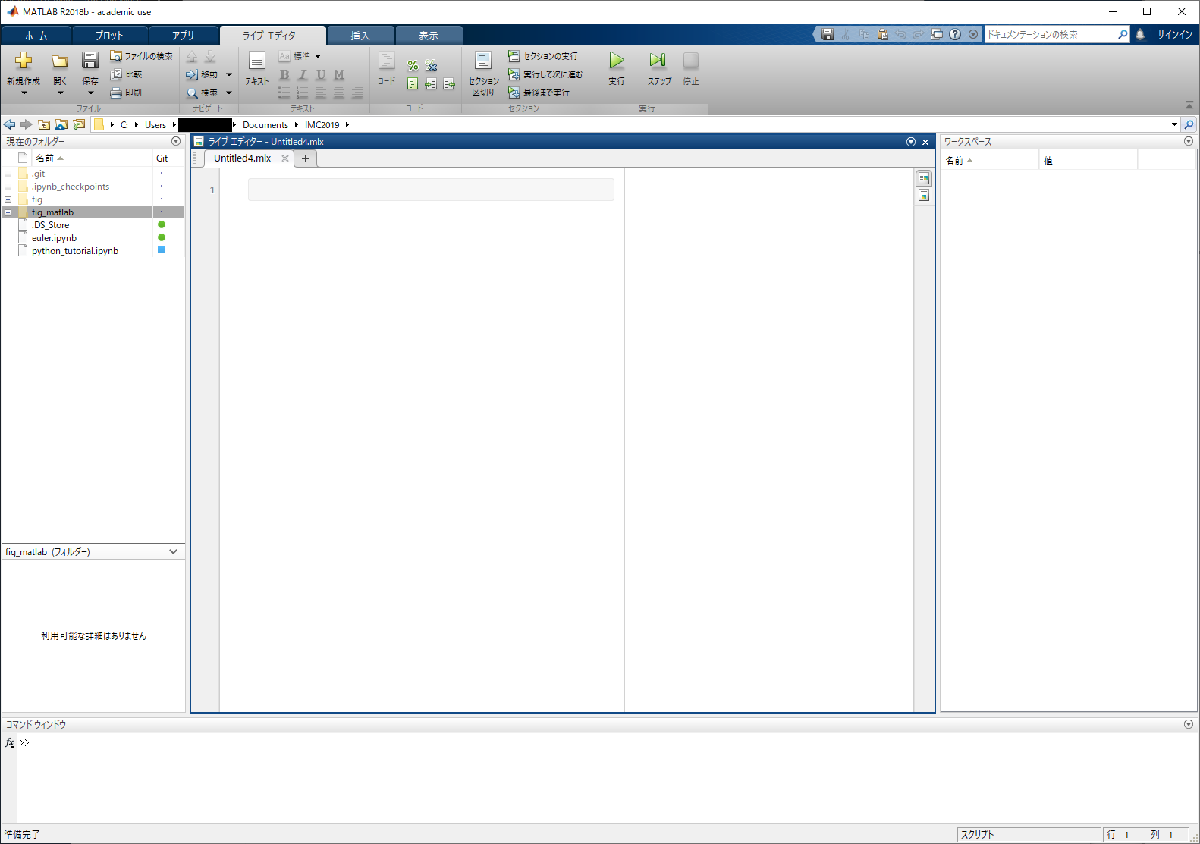

### 4. 実行

    「disp」とは(後にも出てきますが)変数などを表示するための関数です．これを使って制御システム研究室のコアタイムを表示しましょう．まずセルのステータスが「コード」になっていることを確認し，下図のように「disp`('コアタイムは10時30分～18時です')」`と入力してください．その後「実行」を押すとセルのプログラムが実行され実行結果がセルの右（か下）に表示されます．

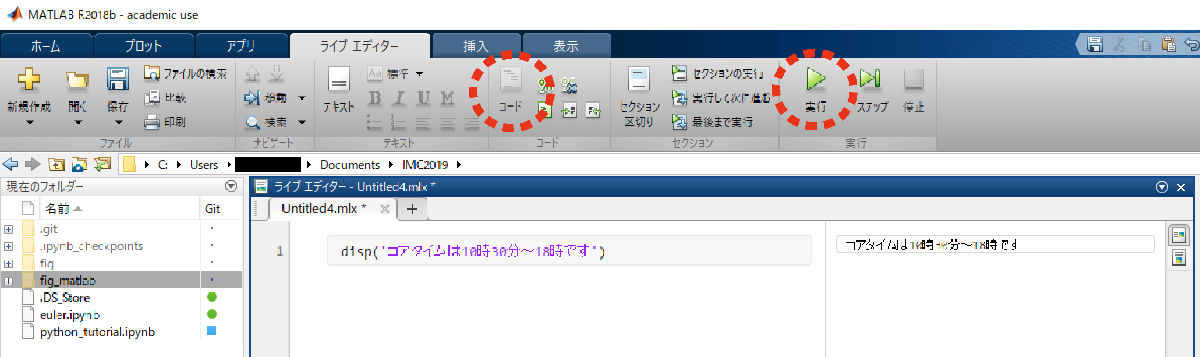

disp('コアタイムは10時30分～18時です')

コアタイムは10時30分～18時です


MALAB Live Editor の基本的な使い方は以上です．ほかの機能については以下の図か，Google先生に聞いてください．

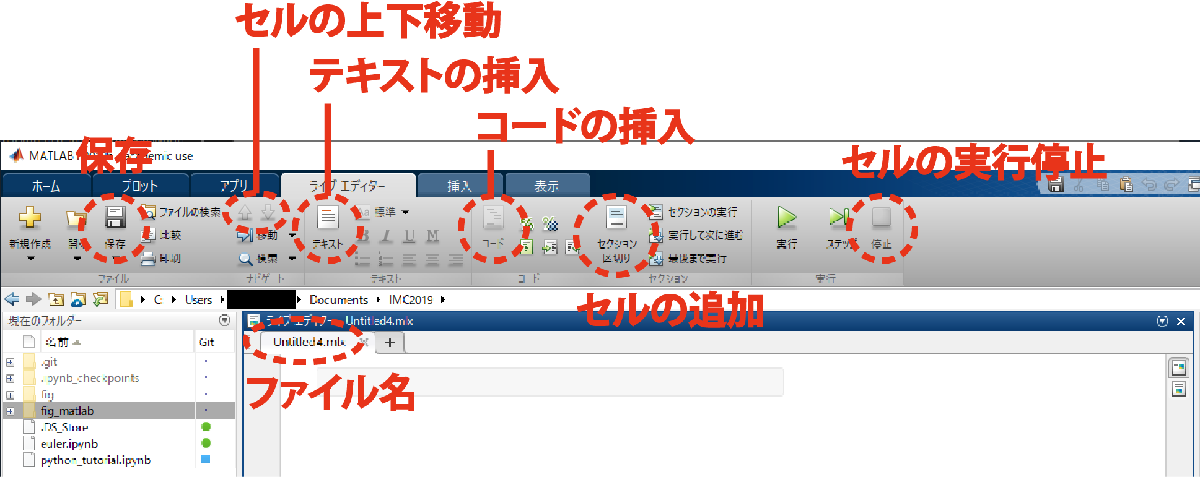

## データと計算

プログラムの主な目的はデータを加工して新しいデータを作り出すことです． 研究のプログラムでは主に次の3種類のデータを扱います．

- 数値・・・例）日付、時刻、信号、パラメータ

- 文字列・・・例）ファイル名、グラフのラベル、シミュレーションの記録

- 行列・・・例）線形代数、状態空間、座標データ

MATLABは数値と文字列を扱うことができ，また行列も扱うことができます．

以下ではそれぞれのデータについての紹介とプログラム例を示します．

### 数値

数字と記号を使って基本的な数値計算をすることができます． 試しにいくつかの数式を打ち込んで表示してみましょう．

123 + 123

ans = 246

123 - 123

ans = 0

123 * 123

ans = 15129


1.23 + 1.23

ans = 2.4600

1.23 - 1.23

ans = 0

1.23 * 1.23

ans = 1.5129


123 + 1.23

ans = 124.2300

123 - 1.23

ans = 121.7700

123 * 1.23

ans = 151.2900

代入演算子「=」を使わない場合の計算結果は「ans」という変数に格納されます．「ans」に値が入っている状態で再度計算を行うと，その計算結果が「ans」に上書きされます．

123 / 123

ans = 1

これまでに登場した演算子（計算記号）をまとめておきます．

- + ：加算

- - ：減算

- * ：乗算

- / ：除算

計算結果は変数に代入することができます．変数はコンピュータ上のメモリ（記憶領域）に紐付けられたラベルのことで，代入はラベルと値を対応づける処理です．

次のプログラムは計算「12+30」の結果を変数「`ultimate_answer」`に代入します．

ultimate_answer = 12 + 30   % 変数に代入（%以降はコメントと呼ばれ，プログラムで処理されず無視されます．）

ultimate_answer = 42

                            % コメントはメモに便利です．

この「`=」`は等しいことを意味せず，単に変数名と値の対応を示すだけです． そのため変数に対応づける値を変えたり，変数の値を使って変数自体を更新することができます．

odyssey = 2001

odyssey = 2001


odyssey = 2010

odyssey = 2010


odyssey = odyssey + 51

odyssey = 2061


odyssey = odyssey + 940

odyssey = 3001

#### 練習問題

次の例題をやってみましょう．

- 4+3を計算し，結果を表示してください．

- $3^2$と$2^3$の和を計算し，結果を表示してください．

- 数値3を変数aに，数値2を変数bに割り当てて，これらの変数を使って問題2を解いてください．解けたら変数を変えて再計算してみてください．

% 1

% 2

% 3


### 文字列

MATLABの文字列は '文字列' あるいは "文字列" のように定義することができます．

文字列はダブルクォート「"」またはシングルクォート「'」で囲うことでデータとして扱えます．

disp("hello, world!")

hello, world!


数値と同様に，変数への代入ができます． 文字列に対しては演算子「`+」`が定義されていて，2つの文字列を結合できます．

s1 = "たけやぶやけた"

s1 = "たけやぶやけた"

s2 = 'あいうえお'

s2 = 'あいうえお'

disp(s1 + s2)

たけやぶやけたあいうえお


文字列の中に数値（例えばそれ以前に処理した計算結果）を埋め込むこともできます． これは次の例を見るほうがわかりやすいでしょう．

odyssey1 = 2001

odyssey1 = 2001

odyssey2 = 2010

odyssey2 = 2010

odyssey3 = odyssey2 + 51

odyssey3 = 2061

odyssey4 = odyssey3 + 940

odyssey4 = 3001


title1 = "An odyssey in " + odyssey1

title1 = "An odyssey in 2001"

title2 = "An odyssey in " + odyssey2

title2 = "An odyssey in 2010"

title3 = "An odyssey in " + odyssey3

title3 = "An odyssey in 2061"

title4 = "An odyssey in " + odyssey4

title4 = "An odyssey in 3001"


disp(title1)

An odyssey in 2001


disp(title2)

An odyssey in 2010


disp(title3)

An odyssey in 2061


disp(title4)

An odyssey in 3001


**練習問題**

- 変数`core_hour`と`core_minute`に制御システム研究室のコアタイムの時間，分を数値として代入し，`コアタイムはHH:MM`の形式で表示してください．

% 1


### 行列

MATLABには標準で行列を扱う機能があります．

行列計算を使ったプログラム例を示します．このプログラムは$2\times 2$行列$A,B$の内積$C$を計算します．記号を大文字にしたのは趣味です．

A = [ 1  2 ;  3  4 ]

A =      1     2
     3     4


B = [ 5  6 ;
      7  8 ]

B =      5     6
     7     8



C = A * B

C =     19    22
    43    50


1~3行目で行列A, Bを定義し，5行目で内積を計算します．

行列同士の演算は内積以外にも，

- 要素和

- 要素差

- 要素積

- 要素商

などが定義されています．

A = [ 1  2 ;
      3  4 ]

A =      1     2
     3     4


B = [ 5  6 ;
      7  8 ]

B =      5     6
     7     8


  
disp("Aの転置")

Aの転置


disp(A')

     1     3
     2     4




disp("要素和")

要素和


disp(A + B)

     6     8
    10    12




disp("要素差")

要素差


disp(A - B)

    -4    -4
    -4    -4




disp("要素積")

要素積


disp(A .* B)

     5    12
    21    32




disp("要素商")

要素商


disp(A ./ B)

    0.2000    0.3333
    0.4286    0.5000



行列の「i」列「j」行要素を取り出すには次のようにします．インデックスは1スタートです．

A = [ 1  2 ;
      3  4 ]

A =      1     2
     3     4



disp("1, 1要素")

1, 1要素


disp(A(1,1))

     1




disp("2, 1要素")

2, 1要素


disp(A(2,1))

     3



また，逆行列，行列式の計算は以下のように行います．

A = [ 1  2 ;
      3  4 ]

A =      1     2
     3     4


  
disp("逆行列")

逆行列


disp(inv(A))

   -2.0000    1.0000
    1.5000   -0.5000




disp("行列式")

行列式


disp(det(A))

    -2



#### 練習問題

        1. 次の連立方程式を逆行列を使って計算してみましょう．

            
$$\left\{ \begin{array}{r} x+3y=1 \\ 4x+5y=7 \end{array}$$


        2. 適当な2×2の正方行列に対して「inv()」の結果と逆行列の公式，

            
$$A^{-1} ={\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack }^{-1} =\frac{1}{\left|A\right|}\left\lbrack \begin{array}{cc}
d & -b\\
-c & a
\end{array}\right\rbrack$$


            の結果が一致することを確認しましょう．

% 1

% 2


**その他のデータ型**

上で挙げた数値，文字列，行列以外にもデータ型はあります．しかし研究のプログラムでは扱わない，または明示的に扱う必要がないデータので，列挙して紹介するに留めます．

- 真偽型

`       true（1）`とf`alse(0)`の2値．ブール代数（論理代数）が使える．後述する条件分岐にて説明するのでここでは省略．

## 関数

関数は一般的にあるデータを受け取り，何らかの規則で変換した結果を返すものです．MATLABで関数を作る方法はfunctionを使う方法と@を使う方法がありますが，ここでは@を使った無名関数を作る方法を説明します．無名関数は以下で定義できます．

`lambda 引数:戻り値(処理の内容)`

例えば,次のセルでは受け取った値*𝑥*の平方*𝑥*⎯⎯√を返す関数`sqrt`を定義して、2⎯⎯√を計算しています。